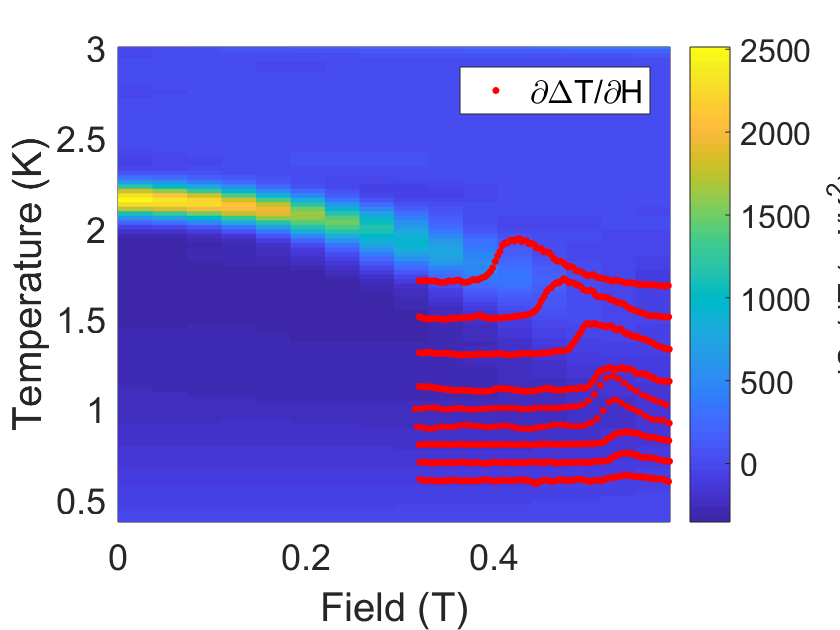

figure
% imagesc([0 hmax/10^4],[.365 3],-d1Cpg)
% axis([0 hmax/10^4 .365 3])% overwrite axis limits of imagesc, which are weird
% surf(Hg./10000,Tg,-d1Cpg,'EdgeColor','none')
h = pcolor(Hg./10000,Tg,-d1Cpg);
h.EdgeColor = 'none';
xlabel('Field (T)')
ylabel('Temperature (K)')
% zlabel('-dCp/dT (uJ/K^2)')
h=colorbar('eastoutside');
h.Label.String = '-dC_p/dT (\muJ/K^2)';
ylim([round(tmin,2) 3])
xlim([0 0.6])
view([0 90])
hold on
% set(gca,'YDir','normal')

% figure
filterSR10 = false(length(sweeprate)+1,1);% initialize logical array
filterSR20 = false(length(sweeprate)+1,1);% initialize logical array
filterSR10(2:end) = sweeprate<15 & sweeprate>5 & Tmce(2:end)>0.85 & Tmce(2:end)<1.05 & Hmce(2:end)/10^4>0.315 & Hmce(2:end)/10^4<0.63;
filterSR20(2:end) = sweeprate<25 & sweeprate>15 & Tmce(2:end)>0.55 & Hmce(2:end)/10^4>0.32 & Hmce(2:end)/10^4<0.63;
p1 = plot(Hmce(filterSR20)./10000,Tmce(filterSR20)+mcediff(filterSR20),'.r');
hold on
plot(Hmce(filterSR10)./10000,Tmce(filterSR10)+mcediff(filterSR10),'.r')
legend([p1],'\partial\DeltaT/\partialH')